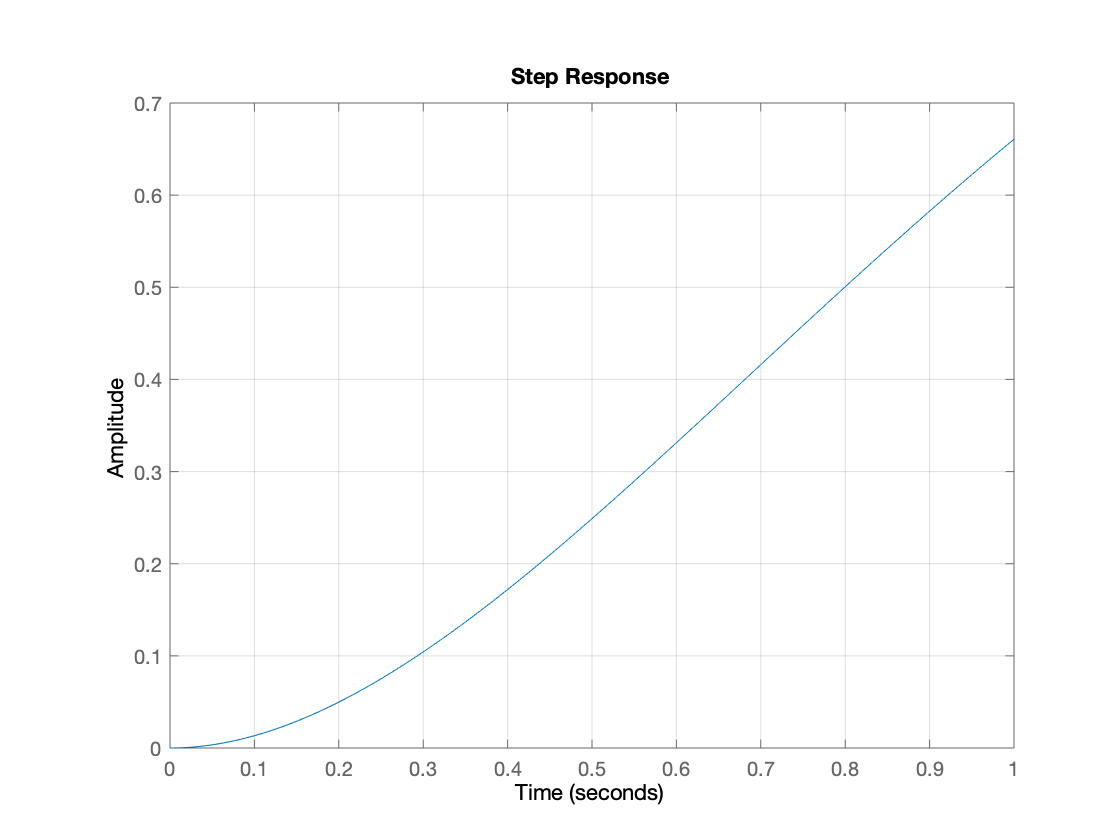

K = 2.8615;
num = K;
den = [1];
sysA = tf(num,den);
%
num = 1;
den = [1 2 0];
sysB = tf(num,den);
%
sysOLT = sysA*sysB;
%
sysfeed = feedback(sysOLT,1);

t = 0: 0.002 : 1;
step(sysfeed,t); grid

stepinfo(sysfeed)

ans = struct with fields:
        RiseTime: 1.0842
    SettlingTime: 3.5031
     SettlingMin: 0.9025
     SettlingMax: 1.1000
       Overshoot: 9.9999
      Undershoot: 0
            Peak: 1.1000
        PeakTime: 2.3026


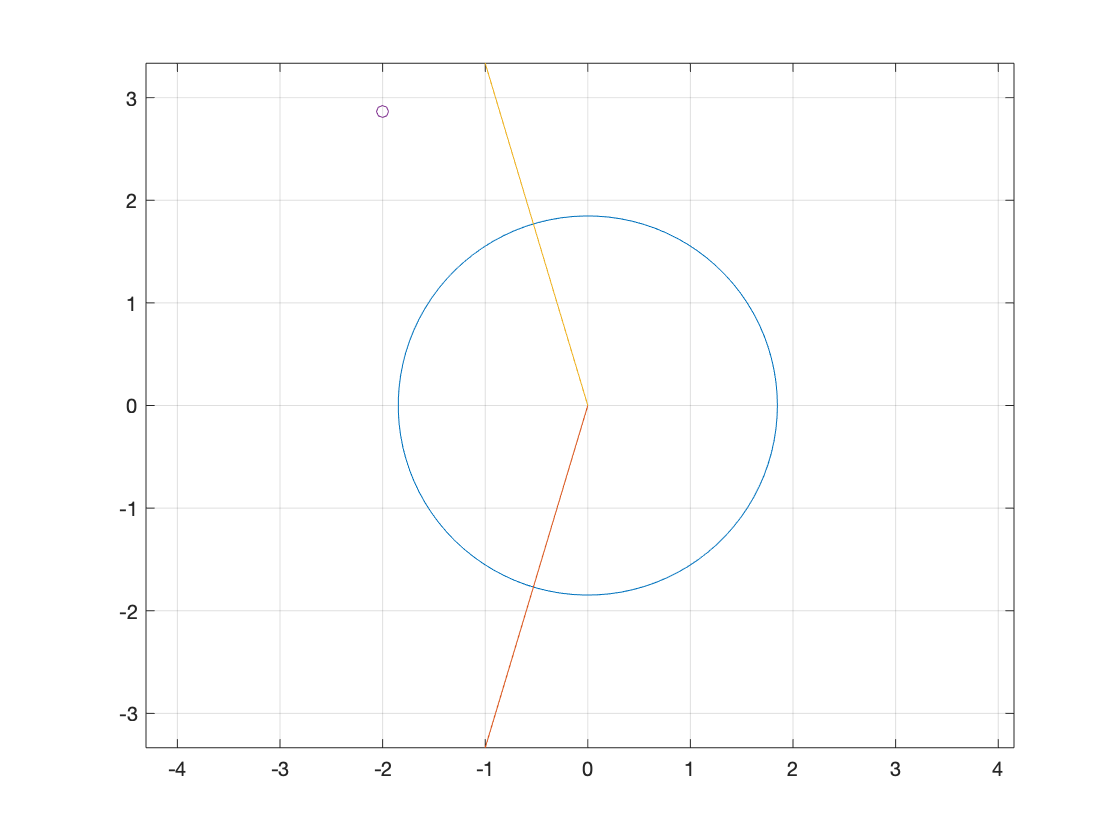

% K = 2.8615;
% num = K;
% den = [1];
% sysA = tf(num,den);
% %
% num = 1;
% den = [1 2 0];
% sysB = tf(num,den);
% %
% sysOLT = sysA*sysB;
% %
% sysfeed = feedback(sysOLT,1);
% 
% t = 0: 0.002 : 1;
% step(sysfeed,t); grid
% stepinfo(sysfeed)

r = 1.8477;
xc = 0;
yc = 0;
theta = linspace(0,2*pi);
xr = r*cos(theta)+ xc;
yr = r*sin(theta) + yc;
plot(xr,yr)
axis equal
hold on

x = linspace(0,-1,20);
y = 3.3361*x;
plot(x,y)
hold on
plot(x,-y)
grid on
s = -2;
im = 2.8615;
scatter(s,im,'o')